# Math 244: MATLAB Assignment 2

### Name: Chance Reyes

### RUID: 225006531

### Date: 2/9/25

clear;
close all;
clc;

## 2.

% Call Euler's Method with the specific parameters given and compute the
% error in the solution

f = @(t,y) exp(t) - t;       % RHS of the differential equation
fSol = @(t) exp(t) - t.^2/2; % Solution to the IVP


dt = 0.2;
Tf = 2;
t0 = 0;
y0 = 1;

[t,y] =  eulerMethod(f, dt, Tf, t0, y0);
trueSol = fSol(2);

error = abs(y(end) - trueSol);

disp("output:");

output:


disp(y);

    1.0000    1.2000    1.4043    1.6226    1.8671    2.1522    2.4958    2.9199    3.4509    4.1215    4.9714



disp("error:");

error:


disp(error);

    0.4176



## 3. 

stepSize = [0.1, 0.05, 0.01, 0.005, 0.001, 0.0005, 0.0001, 0.00005];
error = zeros(1,length(stepSize));


for ind = 1:length(stepSize)
    % Find the error for each step-size and store it in error
   [t,y] =  eulerMethod(f, stepSize(ind), Tf, t0, y0);
    
   error(ind) = abs(y(end) - trueSol);
    
end
disp("errors:")

errors:


disp(error)

    0.2141    0.1084    0.0219    0.0110    0.0022    0.0011    0.0002    0.0001



## 4.

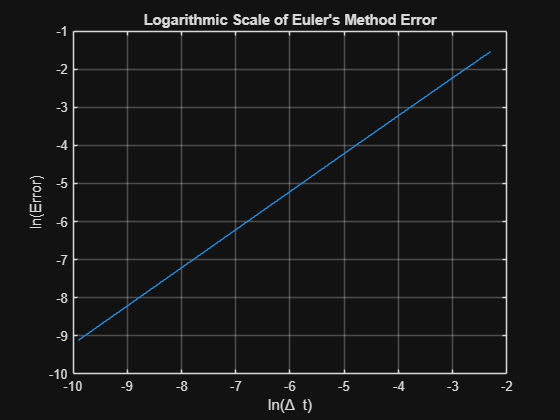

% Plotting code here
lnStepSize = log(stepSize);
lnError = log(error);

figure;
plot(lnStepSize,lnError);
xlabel('ln(\Delta t)');
ylabel('ln(Error)');
grid on
title("Logarithmic Scale of Euler's Method Error");

## 5. 

y = log(error)';
x = log(stepSize)';
xMat = [ones(length(stepSize), 1), x];
bestFit = xMat\y;
slope = bestFit(2);
intercept = bestFit(1);

% Display which of these numbers you need using disp();
disp("Slope:");

Slope:


disp(slope);

    0.9975



## 6. 

disp("Order:");

Order:


disp(round(slope));

     1



## 7. 

% Repeat the code for Runge Kutta Method here
stepSize = [0.1, 0.07, 0.05, 0.02, 0.01, 0.007, 0.005, 0.003];


for ind = 1:length(stepSize)
    % Find the error for each step-size and store it in error
   [t,y] =  rungeKuttaMethod(f, stepSize(ind), Tf, t0, y0);
    
   error(ind) = abs(y(end) - trueSol);
    
end
disp("errors:")

errors:


disp(error)

   1.0e-06 *

    0.2218    0.0502    0.0139    0.0004    0.0000    0.0000    0.0000    0.0000



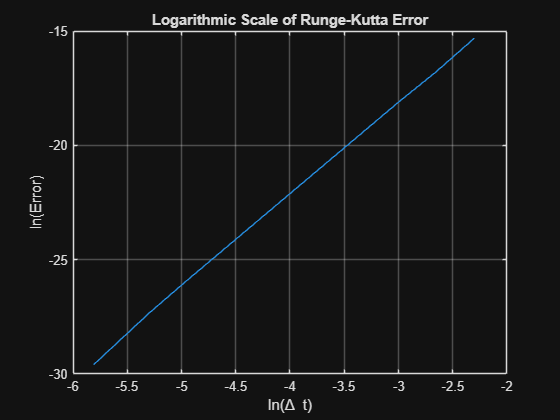


% Plotting
lnStepSize = log(stepSize);
lnError = log(error);

figure;
plot(lnStepSize,lnError);
xlabel('ln(\Delta t)');
ylabel('ln(Error)');
grid on
title("Logarithmic Scale of Runge-Kutta Error");


% Slope and Order
y = log(error)';
x = log(stepSize)';
xMat = [ones(length(stepSize), 1), x];
bestFit = xMat\y;
slope = bestFit(2);
intercept = bestFit(1);

disp("slope:");

slope:


disp(slope);

    4.0314



disp("order:");

order:


disp(round(slope));

     4



## 8. 

% Set up and plot the graphs here
dt = 0.1

dt = 0.1000

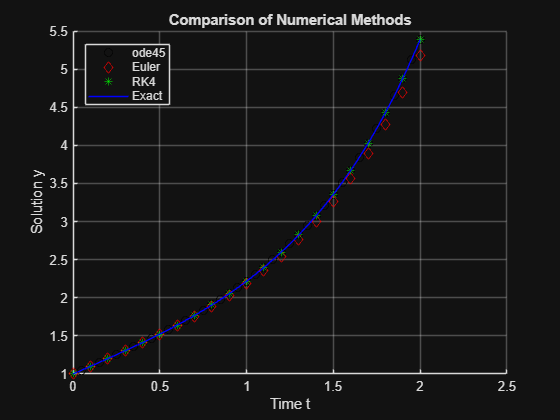

[ode45_t, ode45_y] = ode45(f, [0,2], y0);
[euler_t, euler_y] = eulerMethod(f, dt, Tf, t0, y0);
[rk_t, rk_y] = rungeKuttaMethod(f, dt, Tf, t0, y0);
tspan = linspace(0, 2, 100);
y_exact = fSol(tspan);

% Plot
figure;
hold on;
plot(ode45_t, ode45_y, 'ko', 'DisplayName', 'ode45');
plot(euler_t, euler_y, 'rd', 'DisplayName', 'Euler');
plot(rk_t, rk_y, 'g*', 'DisplayName', 'RK4');
plot(tspan, y_exact, 'b-', 'DisplayName', 'Exact');
xlabel('Time t');
ylabel('Solution y');
title('Comparison of Numerical Methods');
legend('Location', 'Best');
grid on;
hold off;

## Functions - #1

function [t,y] =  eulerMethod(f, dt, Tf, t0, y0)

t(1) = t0;
y(1) = y0;
numSteps = (Tf - t0)/dt;
for ind=1:numSteps
% Add code to these three lines here and remove the comments at the start.
    m = f(t(ind), y(ind));
    t(ind+1) = t(ind) + dt ;
    y(ind+1) = y(ind) + dt*m;
end

end
